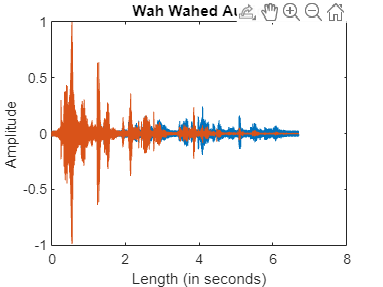

infile = 'Audio files\tale_tone_48000.wav';
% Read in Audio File
[ audio_in, fs] = audioread(infile);
%Prompt for and store 'Damping', 'Min_Cutoff' and 'Max_Cutoff' and 'Width' Variables
damping = 0.02;
width = 1000;
min_cutoff = 250;
max_cutoff = 8000;
centre_freq = width/fs;

cutoff_freq = min_cutoff:centre_freq:max_cutoff;
while(length(cutoff_freq) < length(audio_in) )
cutoff_freq = [ cutoff_freq (max_cutoff:-centre_freq:min_cutoff) ];
cutoff_freq = [ cutoff_freq (min_cutoff:centre_freq:max_cutoff) ];
end

cutoff_freq = cutoff_freq(1:length(audio_in));

%The Filtering coefficients F1 and Q1 are used to control the centre frequency and Q 
F1 = 2*sin((pi*cutoff_freq(1))/fs);
Q1 = 2*damping;

% Create and Zero Vectors to Match Length of Audio Input File
highpass=zeros(size(audio_in));
bandpass=zeros(size(audio_in));
lowpass=zeros(size(audio_in));

highpass(1) = audio_in(1);
bandpass(1) = F1*highpass(1);
lowpass(1) = F1*bandpass(1);

%Followed by the differential equation:
for n=2:length(audio_in)
    highpass(n) = audio_in(n) - lowpass(n-1) - Q1*bandpass(n-1);
    bandpass(n) = F1*highpass(n) + bandpass(n-1);
    lowpass(n) = F1*bandpass(n) + lowpass(n-1);
    F1 = 2*sin((pi*cutoff_freq(n))/fs);
end

normed = bandpass./max(max(abs(bandpass)));
audiowrite('wah wahed.wav', normed, fs);
sound (normed, fs);

%Plots
t1=0:1/fs:(length(audio_in)-1)/fs;
figure(1);
plot(t1,audio_in);
title('Original Audio');
ylabel('Amplitude');
xlabel('Length (in seconds)');
hold all;
t2=0:1/fs:(length(normed)-1)/fs;
figure(1);
plot(t2,normed);
title('Wah Wahed Audio');
ylabel('Amplitude');
xlabel('Length (in seconds)');

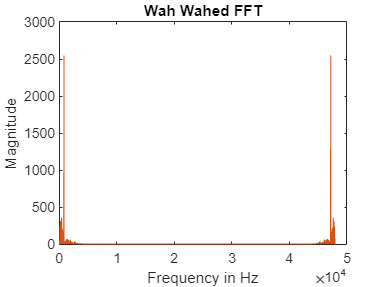

n=length(audio_in)-1;
f1=0:fs/n:fs;
audio_infft=abs(fft(audio_in));
figure(2);
plot(f1,audio_infft);
xlabel('Frequency in Hz');
ylabel('Magnitude');
title('The Audio Input FFT');
hold all;
n=length(normed)-1;
f1=0:fs/n:fs;
normedfft=abs(fft(audio_in));
figure(2);
plot(f1,normedfft);
xlabel('Frequency in Hz');
ylabel('Magnitude');
title('Wah Wahed FFT');